# q Investigation

Live script to find alpha small q, given alpha Q1 Q2. From Q1 and Q1/Q2 Investigation we get 0.60.

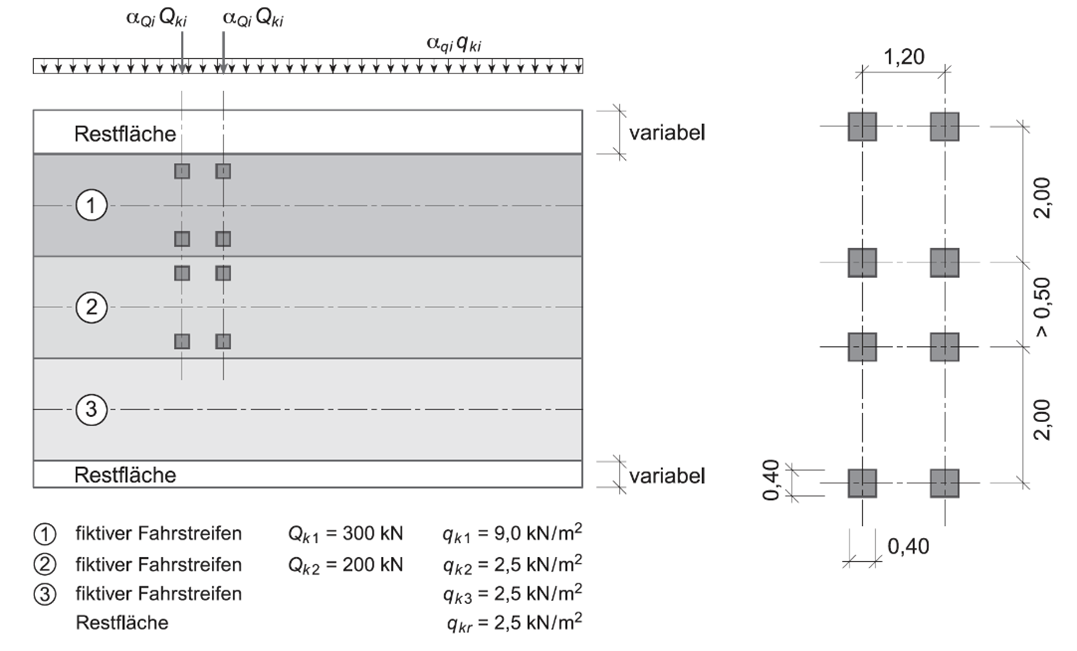

This is part of an initial effort to estimate alpha q using OBSERVED WIM. We will then move to sims

- For now we use the same bridge lengths/configs as in AGB 2002/005

% Initial commands
clear, clc, close all
% This function loads the variable 'MaxEvents' which is produced by 'MATSimAxles'
load('qMaxEvents.mat');
load('ESIAWIM.mat');
load('InflWIM.mat');
% Convert ClassT to m (number) form m = 1 is All, m = 2 is ClassOW, m = 3 is Class
MaxEvents.m(strcmp(MaxEvents.ClassT,"All")) = 1;
MaxEvents.m(strcmp(MaxEvents.ClassT,"ClassOW")) = 2;
MaxEvents.m(strcmp(MaxEvents.ClassT,"Class")) = 3; MaxEvents.ClassT = [];
% Alter Speed
MaxEvents.L1Sp = MaxEvents.L1Sp/100;
MaxEvents.L2Sp = MaxEvents.L2Sp/100;

### Step 1: Input desired filters/parameters

% Select which year to analyze
Years = 0;
%Years = 2011:2019;

% Select stations (locations) to analyze
Stations = 0;
%Stations = [408 409 405 406 402 415 416];

% Block Maxima (always use j)
BM = {'Daily', 'Weekly', 'Yearly'};

% Select which Classification you want to analyze (always use i)
% Must be in the order 'All' 'ClassOW' 'Class' due to deletions
ClassType = {'All', 'ClassOW', 'Class'};
ClassT = {'All', 'Classified+', 'Classified'};

% Must define Action Effects
%AE = {'Mp', 'Mn', 'V'};


### Step 2: Filter Axles based on desired year and station (location)

% Filter Axles based on desired year and station (location)
if Stations > 0
    y = MaxEvents.ZST == Stations;
    MaxEvents(~any(y,2),:) = [];
end
if Years > 0
    y = year(MaxEvents.Time) == Years;
    MaxEvents(~any(y,2),:) = [];
end


### Step 3: Build Structure with Block Maxima



% For each Influence case
for r = 1:length(Infl.Names)
    
    % Reset MaxEvents and select r
    MaxEventsSub = MaxEvents(MaxEvents.InfCase == r,:);
    % Transform AxTandem into Array (necessary for splitapply)
    Z = MaxEventsSub;
    Z.Time = datenum(Z.Time);
    Z = table2array(Z);
    
    for i = 1:length(ClassType)
        Class = ClassType{i};
        
        % Filter based on Class - MaxEvents is compromised after this (deleting entries)
        if strcmp(Class,'ClassOW')
            MaxEventsSub(MaxEventsSub.m == 1,:) = []; %#ok<*SAGROW>
            Z(Z(:,end) == 1,:) = [];
        elseif strcmp(Class,'Class')
            MaxEventsSub(MaxEventsSub.m == 1,:) = [];
            Z(Z(:,end) == 1,:) = [];
            MaxEventsSub(MaxEventsSub.m == 2,:) = [];
            Z(Z(:,end) == 2,:) = [];
        end
        
        for j = 1:length(BM)
            BlockM = BM{j};
            
            % Initialize
            Max(r).(Class).(BlockM) = [];
            
            if strcmp(BlockM,'Daily')
                
                % Make groups out of unique locations and days
                [Gr, GrIDDay, GrIDZST, GrIDInf] = findgroups(dateshift(MaxEventsSub.Time,'start','day'),MaxEventsSub.ZST,MaxEventsSub.InfCase);
               
            elseif strcmp(BlockM,'Weekly')
                
                [Gr, GrIDWeek, GrIDZST, GrIDInf] = findgroups(dateshift(MaxEventsSub.Time,'start','week'),MaxEventsSub.ZST,MaxEventsSub.InfCase);
                
            else
                
                [Gr, GrIDYear, GrIDZST, GrIDInf] = findgroups(year(MaxEventsSub.Time),MaxEventsSub.ZST,MaxEventsSub.InfCase);
                
            end
            
            % Perform splitapply (see function at end... not just Max as we want whole rows involving maxes)
            Max(r).(Class).(BlockM) = splitapply(@(Z)maxIndex(Z),Z,Gr);
            % Transform back into table form
            Max(r).(Class).(BlockM) = array2table(Max(r).(Class).(BlockM));
            Max(r).(Class).(BlockM).Properties.VariableNames = {'R', 'ZST', 'Max', 'InfCase', 'DayRank', 'L1Veh', 'L2Veh', 'L1Load', 'L2Load', 'L1Ax', 'L2Ax', 'L1Sp', 'L2Sp', 'Time', 'm'};
            Max(r).(Class).(BlockM).Time = datetime(Max(r).(Class).(BlockM).Time,'ConvertFrom',"datenum"); Max(r).(Class).(BlockM).R = [];
            
        end
    end
end

#### Curve Fitting

% Set Distribution Types
DistTypes = {'Normal', 'Lognormal'};%, 'GeneralizedExtremeValue'};

% Set CDF Scaling Factors for estimates
D2WFactor = 5; W2YFactor = 50; D2YFactor = D2WFactor*W2YFactor;

% Set x values to be use globally
x_values = 0:250:50000;

% Have to add a loop for each InfCase... add a column for each InfCase?

% For each Influence Case
for r = 1:length(Infl.Names)

    % Fit Block Maxima to Normal Curve
    for i = 1:length(ClassType)
        Class = ClassType{i};
        
        for j = 1:length(BM)
            BlockM = BM{j};
            
            for k = 1:length(DistTypes)
                Dist = DistTypes{k};
                
                pd(r).(Class).(BlockM).(Dist) = fitdist(Max(r).(Class).(BlockM).Max,Dist);
                y_values(r).(Class).(BlockM).(Dist).PDF_Fit = pdf(pd(r).(Class).(BlockM).(Dist),x_values);
                y_values(r).(Class).(BlockM).(Dist).CDF_Fit = cdf(pd(r).(Class).(BlockM).(Dist),x_values);
                
                if strcmp(BlockM,'Daily')
                    y_values(r).(Class).('Weekly').(Dist).CDF_D2W = y_values(r).(Class).(BlockM).(Dist).CDF_Fit.^D2WFactor;
                    y_values(r).(Class).('Weekly').(Dist).PDF_D2W = [0 diff(y_values(r).(Class).('Weekly').(Dist).CDF_D2W)];
                    y_values(r).(Class).('Yearly').(Dist).CDF_D2Y = y_values(r).(Class).(BlockM).(Dist).CDF_Fit.^D2YFactor;
                    y_values(r).(Class).('Yearly').(Dist).PDF_D2Y = [0 diff(y_values(r).(Class).('Yearly').(Dist).CDF_D2Y)];
                    
                    if strcmp(Dist,'Normal')
                        mu = trapz(y_values(r).(Class).('Weekly').(Dist).CDF_D2W,x_values);
                        sigma = sqrt(trapz(y_values(r).(Class).('Weekly').(Dist).CDF_D2W,(x_values-mu).^2));
                        pd(r).(Class).D2W.(Dist) = makedist(Dist,"mu",mu,"sigma",sigma);
                        
                        mu = trapz(y_values(r).(Class).('Yearly').(Dist).CDF_D2Y,x_values);
                        sigma = sqrt(trapz(y_values(r).(Class).('Yearly').(Dist).CDF_D2Y,(x_values-mu).^2));
                        pd(r).(Class).D2Y.(Dist) = makedist(Dist,"mu",mu,"sigma",sigma);
                    elseif strcmp(Dist,'Lognormal')
                        mu = trapz(y_values(r).(Class).('Weekly').(Dist).CDF_D2W,x_values);
                        sigma = sqrt(trapz(y_values(r).(Class).('Weekly').(Dist).CDF_D2W,(x_values-mu).^2));
                        zeta = sqrt(log(1+(sigma/mu)^2));
                        lambda = log(mu)-0.5*zeta^2;
                        pd(r).(Class).D2W.(Dist) = makedist(Dist,"mu",lambda,"sigma",zeta);
                        
                        mu = trapz(y_values(r).(Class).('Yearly').(Dist).CDF_D2Y,x_values);
                        sigma = sqrt(trapz(y_values(r).(Class).('Yearly').(Dist).CDF_D2Y,(x_values-mu).^2));
                        zeta = sqrt(log(1+(sigma/mu)^2));
                        lambda = log(mu)-0.5*zeta^2;
                        pd(r).(Class).D2Y.(Dist) = makedist(Dist,"mu",lambda,"sigma",zeta);
                    end
                    
                elseif strcmp(BlockM,'Weekly')
                    y_values(r).(Class).('Yearly').(Dist).CDF_W2Y = y_values(r).(Class).(BlockM).(Dist).CDF_Fit.^W2YFactor;
                    y_values(r).(Class).('Yearly').(Dist).PDF_W2Y = [0 diff(y_values(r).(Class).('Yearly').(Dist).CDF_W2Y)];
                    
                    if strcmp(Dist,'Normal')
                        mu = trapz(y_values(r).(Class).('Yearly').(Dist).CDF_W2Y,x_values);
                        sigma = sqrt(trapz(y_values(r).(Class).('Yearly').(Dist).CDF_W2Y,(x_values-mu).^2));
                        pd(r).(Class).W2Y.(Dist) = makedist(Dist,"mu",mu,"sigma",sigma);
                        
                    elseif strcmp(Dist,'Lognormal')
                        mu = trapz(y_values(r).(Class).('Yearly').(Dist).CDF_W2Y,x_values);
                        sigma = sqrt(trapz(y_values(r).(Class).('Yearly').(Dist).CDF_W2Y,(x_values-mu).^2));
                        zeta = sqrt(log(1+(sigma/mu)^2));
                        lambda = log(mu)-0.5*zeta^2;
                        pd(r).(Class).W2Y.(Dist) = makedist(Dist,"mu",lambda,"sigma",zeta);
                        
                    end
                    
                end
            end
        end
    end
end


### Step 4: Plot Block Maxima

Right now we just do for one of the InfCases (say, Mp.Mp40, or # 12)

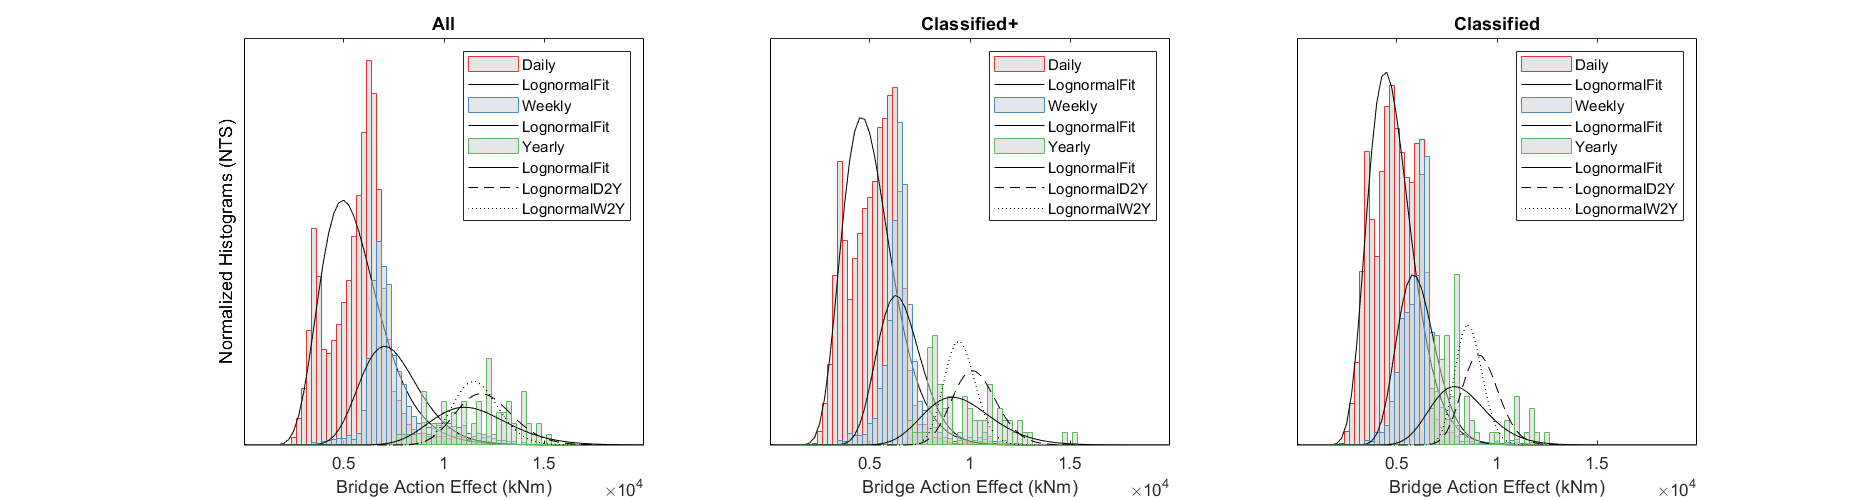

r = 12;

figure('Position',[0 0 1500 400]);

% Set colours
C = linspecer(9);
% ScaleDown
ScaleDown = [1 2.5 5];
% X Stuff
Step = 250;
LimitL = 0;
LimitR = 20000;
X = LimitL:Step:LimitR;
x = X(1:end-1) + diff(X);
    
for i = 1:length(ClassType)
    Class = ClassType{i};
    
    subplot(1,3,i)
    hold on
    
    for j = 1:length(BM)
        BlockM = BM{j};
        
        y = histcounts(Max(r).(Class).(BlockM).Max,'BinEdges',X,'normalization','pdf');
        bar(x,y/ScaleDown(j),1,'EdgeColor',C(j,:),'FaceColor',[.8 .8 .8],'FaceAlpha',0.5,'DisplayName',BlockM)
        
        for k = 2
            Dist = DistTypes{k};
       
            plot(x_values,y_values(r).(Class).(BlockM).(Dist).PDF_Fit/ScaleDown(j),'k-','DisplayName',[Dist 'Fit'])
            
            if strcmp(BlockM,'Yearly')
                
                % Why are these the wrong scale?
                %plot(x_values,y_values(r).(Class).(BlockM).(Dist).PDF_D2Y/ScaleDown(j),'k--','DisplayName',[Dist 'D2Y'])
                %plot(x_values,y_values(r).(Class).(BlockM).(Dist).PDF_W2Y/ScaleDown(j),'k:','DisplayName',[Dist 'W2Y'])
                plot(x_values,pdf(pd(r).(Class).D2Y.(Dist),x_values)/ScaleDown(j),'k--','DisplayName',[Dist 'D2Y'])
                plot(x_values,pdf(pd(r).(Class).W2Y.(Dist),x_values)/ScaleDown(j),'k:','DisplayName',[Dist 'W2Y'])
            end
            
        end
    end
    
    % Set Plot Details
    set(gca,'ytick',[],'yticklabel',[],'ycolor','k')
    box on
    xlim([LimitL+25 LimitR-25])
    if i == 1
        ylabel('Normalized Histograms (NTS)')
    end
    xlabel('Bridge Action Effect (kNm)')
    title([ClassT{i}])
    legend('location','northeast')
    
end

#### *Block Maxima Compared between each other*

Right now we just do for one of the InfCases (say, Mp.Mp40, or # 12)

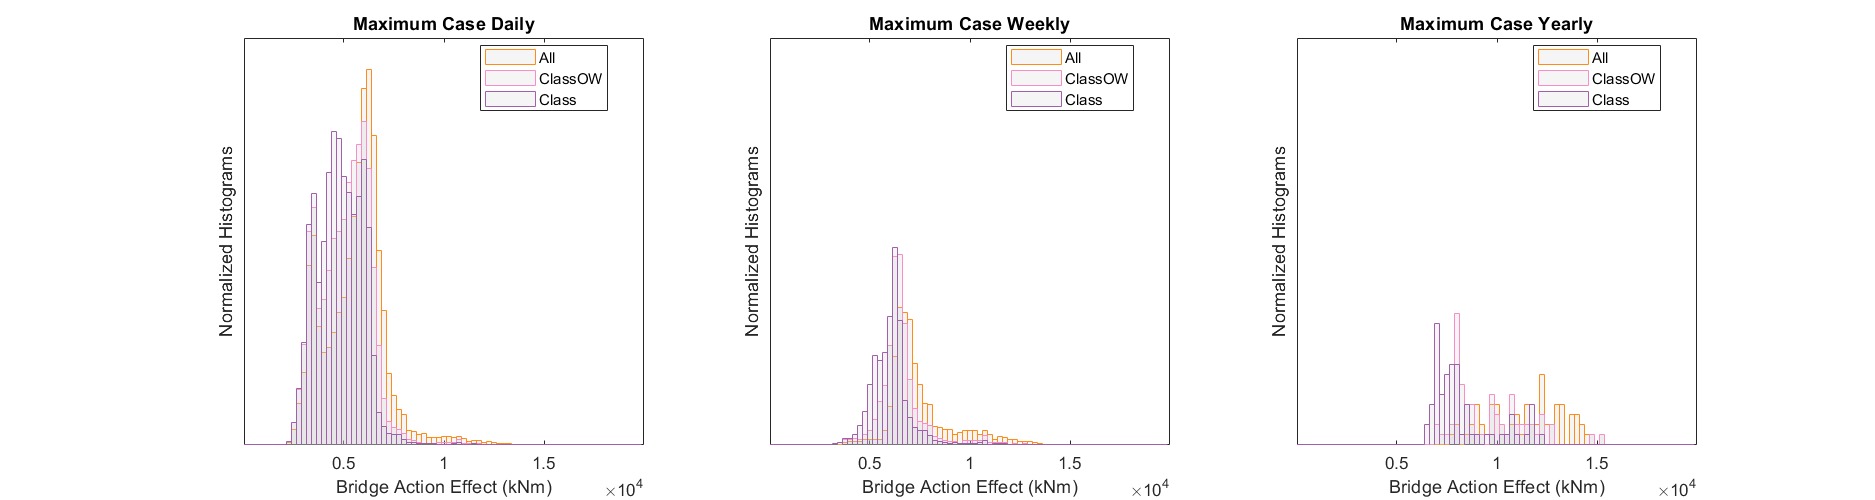

figure('Position',[0 0 1500 400]);

% X Stuff
Step = 250;
LimitL = 0;
LimitR = 20000;
Xp = LimitL-Step/2:Step:LimitR-Step/2;

for j = 1:length(BM)
    BlockM = BM{j};
    
    subplot(1,3,j)
    hold on
    
    histogram(Max(r).All.(BlockM).Max,'BinEdges',Xp,'normalization','pdf','EdgeColor',C(4,:),'FaceColor',[.8 .8 .8],'FaceAlpha',0.2,'DisplayName','All')
    histogram(Max(r).ClassOW.(BlockM).Max,'BinEdges',Xp,'normalization','pdf','EdgeColor',C(7,:),'FaceColor',[.8 .8 .8],'FaceAlpha',0.2,'DisplayName','ClassOW')
    histogram(Max(r).Class.(BlockM).Max,'BinEdges',Xp,'normalization','pdf','EdgeColor',C(9,:),'FaceColor',[.8 .8 .8],'FaceAlpha',0.2,'DisplayName','Class')
    
    % Set Plot Details
    a = ylim;
    ylim([a(1) a(2)*j])
    box on
    set(gca,'ytick',[],'yticklabel',[])
    ylabel('Normalized Histograms')
    xlabel('Bridge Action Effect (kNm)')
    title(['Maximum Case ' BlockM])
    legend('location','best')
    xlim([LimitL+25 LimitR-25])
    
end

#### *Block Maxima Compared for Classification Filters*

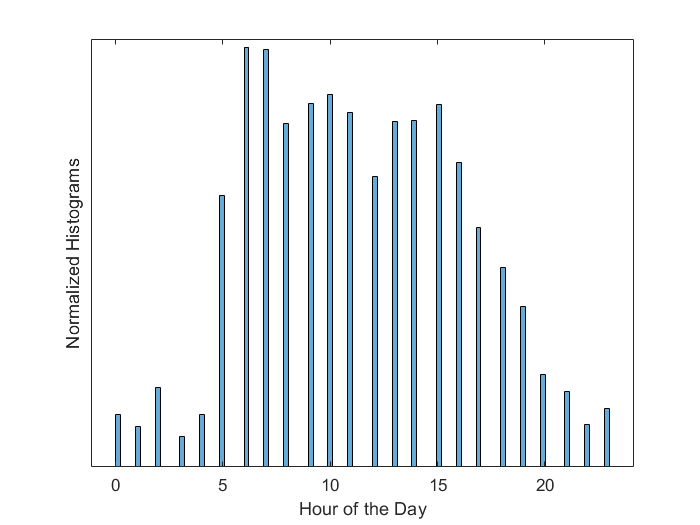

close all,
r = 12;

% Get histogram of speeds
histogram(hour(Max(r).All.Daily.Time),100,'normalization','pdf')
box on
set(gca,'ytick',[],'yticklabel',[])
ylabel('Normalized Histograms')
xlabel('Hour of the Day')

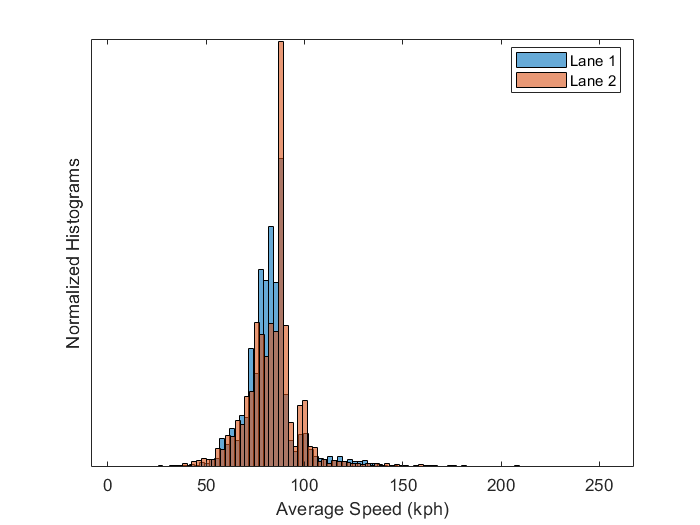


histogram(Max(r).All.Daily.L1Sp(Max(r).All.Daily.L1Sp > 0),100,'normalization','pdf','DisplayName','Lane 1')
hold on
histogram(Max(r).All.Daily.L2Sp(Max(r).All.Daily.L2Sp > 0),100,'normalization','pdf','DisplayName','Lane 2')
legend('location','best')
box on
set(gca,'ytick',[],'yticklabel',[])
ylabel('Normalized Histograms')
xlabel('Average Speed (kph)')

#### *Vehicle Speeds*

### Step 5: Summarize $\alpha_Q$ Estimates

*We account for the fact that the reliability index, *$\beta$, *must be for the same reference period as *$E_{m,\textrm{act}}$

Normal Distribution:                            $E_{d,\textrm{act}} =E_{m,\textrm{act}} \cdot \left\lbrack 1+\alpha \beta \nu \right\rbrack$

Lognormal Distribution:                      $E_{d,\textrm{act}} =E_{m,\textrm{act}} \cdot \exp \left\lbrack \alpha \beta \delta -0\ldotp 5\delta^2 \right\rbrack$      where         $\delta^2 =\ln \left(\nu^2 +1\right)$

% According to Annex C of SIA 269
Beta.Yearly = 4.7; % Here we use the Beta annual - so we should use annual max effects
Beta.Weekly = 5.44422; % See Tail Fitting > Beta Conversion
Beta.Daily = 5.72397;
Alpha = 0.7;

% Right now we assume a normal distribution in the Edact calculation. Also
% perform for lognormal.

% For each Influence Case
for r = 1:length(Infl.Names)
    
    % Initialize SumTable
    ST(r).SumTableNorm = array2table(zeros(6,length(BM)*length(ClassType)));
    ST(r).SumTableLogNormComp = array2table(zeros(5,length(BM)*length(ClassType)));
    ST(r).SumTableNorm.Properties.VariableNames = {[BM{3} ' ' ClassType{3}], [BM{3} ' ' ClassType{2}], [BM{3} ' ' ClassType{1}], [BM{2} ' ' ClassType{3}],...
        [BM{2} ' ' ClassType{2}], [BM{2} ' ' ClassType{1}], [BM{1} ' ' ClassType{3}], [BM{1} ' ' ClassType{2}], [BM{1} ' ' ClassType{1}]};
    ST(r).SumTableLogNorm = ST(r).SumTableNorm;
    ST(r).SumTableNorm.Properties.RowNames = {'Mu', 'Sigma', 'COV (%)', '95th %', 'Dist 95', 'AlphaQ'};
    ST(r).SumTableLogNorm.Properties.RowNames = {'Lambda', 'Zeta', '95th %', 'Dist 95', 'AlphaQN', 'AlphaQLN'};
    ST(r).SumTableLogNormComp.Properties.RowNames = {'Lambda', 'Zeta', '95th %', 'Dist 95', 'AlphaQLN Est'};
    ST(r).SumTableLogNormComp.Properties.VariableNames = {[BM{3} ' ' ClassType{3}], [BM{3} ' ' ClassType{2}], [BM{3} ' ' ClassType{1}], ['W2Y ' ClassType{3}],...
        ['W2Y ' ClassType{2}], ['W2Y ' ClassType{1}], ['D2Y ' ClassType{3}], ['D2Y ' ClassType{2}], ['D2Y ' ClassType{1}]};
    
    for i = 1:length(ClassType)
        Class = ClassType{i};
        
        for j = 1:length(BM)
            BlockM = BM{j};
            
            Emact = mean(Max(r).(Class).(BlockM).Max);
            Stdev = std(Max(r).(Class).(BlockM).Max);
            COV = Stdev/Emact;
            Delta2 = log(COV^2+1);
            N5 = prctile(Max(r).(Class).(BlockM).Max,95);
            Dist95N = norminv(0.95,pd(r).(Class).(BlockM).Normal.mu,pd(r).(Class).(BlockM).Normal.sigma);
            Dist95LN = logninv(0.95,pd(r).(Class).(BlockM).Lognormal.mu,pd(r).(Class).(BlockM).Lognormal.sigma);
            
            EdactN = Emact*(1+Alpha*Beta.(BlockM)*COV);
            AlphaQN = EdactN/(ESIA.Total(r));
            EdactLN = Emact*exp(Alpha*Beta.(BlockM)*sqrt(Delta2)-0.5*Delta2);
            AlphaQLN = EdactLN/(ESIA.Total(r));
            
            ST(r).SumTableNorm.([BlockM ' ' Class]) = [Emact; Stdev; 100*COV; N5; Dist95N; AlphaQN];
            ST(r).SumTableLogNorm.([BlockM ' ' Class]) = [pd(r).(Class).(BlockM).Lognormal.mu; pd(r).(Class).(BlockM).Lognormal.sigma; N5; Dist95LN; AlphaQN; AlphaQLN];
            
            if strcmp(BlockM,'Weekly')
                pdx = pd(r).(Class).W2Y.Lognormal;
                Delta2 = pdx.sigma^2;
                Emact = exp(pdx.mu+0.5*Delta2);
                ST(r).SumTableLogNormComp.(['W2Y ' Class]) = [pdx.mu; pdx.sigma; prctile(Max(r).(Class).Yearly.Max,95); logninv(0.95,pdx.mu,pdx.sigma); Emact*exp(Alpha*Beta.Yearly*sqrt(Delta2)-0.5*Delta2)/(ESIA.Total(r))];
            elseif strcmp(BlockM,'Daily')
                pdx = pd(r).(Class).D2Y.Lognormal;
                Delta2 = pdx.sigma^2;
                Emact = exp(pdx.mu+0.5*Delta2);
                ST(r).SumTableLogNormComp.(['D2Y ' Class]) = [pdx.mu; pdx.sigma; prctile(Max(r).(Class).Yearly.Max,95); logninv(0.95,pdx.mu,pdx.sigma); Emact*exp(Alpha*Beta.Yearly*sqrt(Delta2)-0.5*Delta2)/(ESIA.Total(r))];
            else
                ST(r).SumTableLogNormComp.([BlockM ' ' Class]) = [pd(r).(Class).(BlockM).Lognormal.mu; pd(r).(Class).(BlockM).Lognormal.sigma; N5; Dist95LN; AlphaQLN];
            end
            
        end
    end
    
end
r = 12;
format bank
disp(ST(r).SumTableNorm)

               Yearly Class    Yearly ClassOW    Yearly All    Weekly Class    Weekly ClassOW    Weekly All    Daily Class    Daily ClassOW    Daily All
               ____________    ______________    __________    ____________    ______________    __________    ___________    _____________    _________

    Mu            8246.00          9596.61        11506.19       6065.95          6585.01          7493.82       4815.27         5080.14        5589.97 
    Sigma         1562.96          1840.56         1902.61       1038.64          1206.36          1654.39       1126.97         1281.87        1555.23 
    COV (%)         18.95     

disp(ST(r).SumTableLogNorm)

                Yearly Class    Yearly ClassOW    Yearly All    Weekly Class    Weekly ClassOW    Weekly All    Daily Class    Daily ClassOW    Daily All
                ____________    ______________    __________    ____________    ______________    __________    ___________    _____________    _________

    Lambda            9.00             9.15            9.34          8.70             8.78             8.90          8.45            8.50           8.59 
    Zeta              0.17             0.18            0.17          0.16             0.17             0.20          0.24            0.26           0.29 
    95th %        11654.67

disp(ST(r).SumTableLogNormComp)

                    Yearly Class    Yearly ClassOW    Yearly All    W2Y Class    W2Y ClassOW    W2Y All     D2Y Class    D2Y ClassOW    D2Y All 
                    ____________    ______________    __________    _________    ___________    ________    _________    ___________    ________

    Lambda                9.00             9.15            9.34         9.06          9.16          9.36        9.12          9.23          9.39
    Zeta                  0.17             0.18            0.17         0.08          0.08          0.10        0.10          0.11          0.12
    95th %            11654.67         12674.50        14339.5

### Step 5x: Populate WIM, a comparison with AGB and MAT Results Variables

% First choose which result we will use (try Lognormal Weekly and Yearly)

Section = 'Box';

UniqNames = unique(Infl.Names,'stable');
ColumnNames = {'EQ1','EQ2','Eq','YClass','YClassOW','YAll','WClass','WClassOW','WAll','E'};

% Initialize the final matrix/table
X = NaN(8,length(ColumnNames));
XT = array2table(X,'VariableNames',ColumnNames);
SpanDiv = 10;

for r = 1:length(Infl.Names)
    % Get InfName (call it Temp)
    Temp = UniqNames{r}; %Fixed 26.5.20
    % Get Span from InfName
    Span = str2num(Temp(end-1:end));
    % Get Action Effect from InfName
    AE = Temp(1:end-2);
    
    try
        if istable(WIM.(Section).(AE))
            WIM.(Section).(AE).YClass(Span/SpanDiv) = ST(r).SumTableLogNorm.('Yearly Class')(end)*(ESIA.Total(r));
            WIM.(Section).(AE).YClassOW(Span/SpanDiv) = ST(r).SumTableLogNorm.('Yearly ClassOW')(end)*(ESIA.Total(r));
            WIM.(Section).(AE).YAll(Span/SpanDiv) = ST(r).SumTableLogNorm.('Yearly All')(end)*(ESIA.Total(r));
            WIM.(Section).(AE).WClass(Span/SpanDiv) = ST(r).SumTableLogNorm.('Weekly Class')(end)*(ESIA.Total(r));
            WIM.(Section).(AE).WClassOW(Span/SpanDiv) = ST(r).SumTableLogNorm.('Weekly ClassOW')(end)*(ESIA.Total(r));
            WIM.(Section).(AE).WAll(Span/SpanDiv) = ST(r).SumTableLogNorm.('Yearly All')(end)*(ESIA.Total(r));
            
            WIM.(Section).(AE).E(Span/SpanDiv) = ESIA.Total(r);
            WIM.(Section).(AE).Eq(Span/SpanDiv) = ESIA.Eq(r);
            WIM.(Section).(AE).EQ1(Span/SpanDiv) = ESIA.EQ(1,r);
            WIM.(Section).(AE).EQ2(Span/SpanDiv) = ESIA.EQ(2,r);
            
        end
    catch
        WIM.(Section).(AE) = XT;
        
        WIM.(Section).(AE).YClass(Span/SpanDiv) = ST(r).SumTableLogNorm.('Yearly Class')(end)*(ESIA.Total(r));
        WIM.(Section).(AE).YClassOW(Span/SpanDiv) = ST(r).SumTableLogNorm.('Yearly ClassOW')(end)*(ESIA.Total(r));
        WIM.(Section).(AE).YAll(Span/SpanDiv) = ST(r).SumTableLogNorm.('Yearly All')(end)*(ESIA.Total(r));
        WIM.(Section).(AE).WClass(Span/SpanDiv) = ST(r).SumTableLogNorm.('Weekly Class')(end)*(ESIA.Total(r));
        WIM.(Section).(AE).WClassOW(Span/SpanDiv) = ST(r).SumTableLogNorm.('Weekly ClassOW')(end)*(ESIA.Total(r));
        WIM.(Section).(AE).WAll(Span/SpanDiv) = ST(r).SumTableLogNorm.('Yearly All')(end)*(ESIA.Total(r));
        
        WIM.(Section).(AE).E(Span/SpanDiv) = ESIA.Total(r);
        WIM.(Section).(AE).Eq(Span/SpanDiv) = ESIA.Eq(r);
        WIM.(Section).(AE).EQ1(Span/SpanDiv) = ESIA.EQ(1,r);
        WIM.(Section).(AE).EQ2(Span/SpanDiv) = ESIA.EQ(2,r);
        
    end
    
end

### Step 6: Probability Paper Plotting & Tail Fitting Methods

When we apply the above equations, we are assuming the maximums are normally or log-normally distributed. We should evaluate the fit with a probability paper plot.

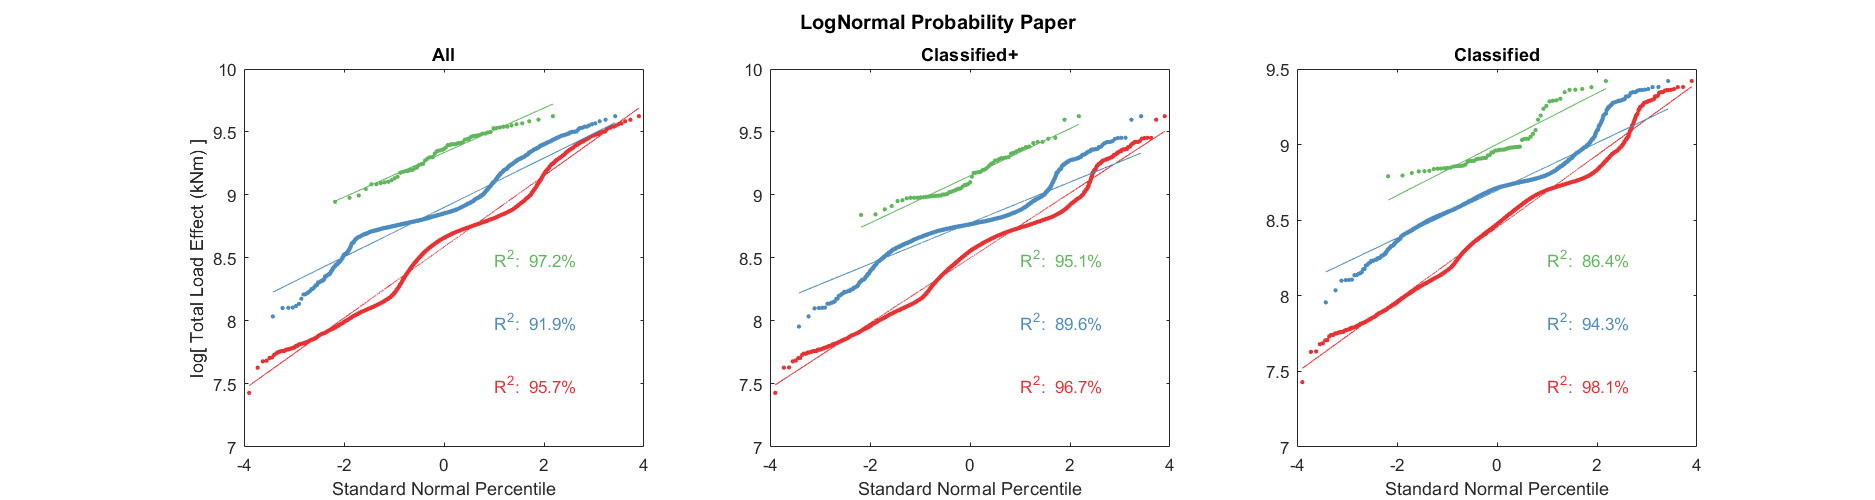

figure('Position',[0 0 1500 400]);


% For each Influence Case
for r = 12
    
    for i = 1:length(ClassType)
        Class = ClassType{i};
        
        for j = 1:length(BM)
            BlockM = BM{j};
            subplot(1,3,i)
            hold on
            
            [MaxECDF, MaxECDFRank] = ecdf(Max(r).(Class).(BlockM).Max); MaxECDFRank = MaxECDFRank'; MaxECDF(1) = []; MaxECDFRank(1) = [];
            
            scatter(norminv((1:length(MaxECDFRank))/(length(MaxECDFRank) + 1)),log(MaxECDFRank),7,C(j,:),'filled','DisplayName','Max Data');
            mdl = fitlm(norminv((1:length(MaxECDFRank))/(length(MaxECDFRank) + 1)),log(MaxECDFRank),'linear');
            
            x2 = norminv((1:length(MaxECDFRank))/(length(MaxECDFRank) + 1));
            y2 = log(MaxECDFRank);
            
            md2 = fitlm(x2(round(length(x2)*3/4):length(x2)),y2(round(length(x2)*3/4):length(x2)),'linear');
            
            plot(norminv((1:length(MaxECDFRank))/(length(MaxECDFRank) + 1)),mdl.Fitted,'-','Color',C(j,:),'DisplayName',['Fitted ' num2str(mdl.Rsquared.Ordinary,3)]);
            %plot(x2(round(length(x2)*3/4):length(x2)),md2.Fitted,'-','Color','k','DisplayName',['Fitted ' num2str(md2.Rsquared.Ordinary,3)]);
            
            
            %text(1,y1(1)+(y1(2)-y1(1))/j,['\lambda = ' sprintf('%.2f \n',mdl.Coefficients.Estimate(1)) '\zeta = ' sprintf('%.2f \n',mdl.Coefficients.Estimate(2)) sprintf('R^2:  %.1f%%',mdl.Rsquared.Ordinary*100)])
            
            box on
            %xlim([-4 4])
            %ylim([3.5 7])
            y1 = ylim;
            text(1,y1(1)+(y1(2)-y1(1))*(j/6),sprintf('R^2:  %.1f%%',mdl.Rsquared.Ordinary*100),"Color",C(j,:))
            
        end
        
        if i == 1
            ylabel('log[ Total Load Effect (kNm) ]')
        end
        xlabel('Standard Normal Percentile')
        %legend('Location', 'southeast')
        title([ClassT{i}])
        
    end
end

sgtitle('LogNormal Probability Paper','fontweight','bold','fontsize',12);

#### Function(s)

function out = maxIndex(Z)
    [ymax, loc]=max(Z(:,2));
    out=[ymax, Z(loc,:)];
end